# Labolatorium 2 - Ortogonalność, ortonormalność, bazy, kodowanie w ethernecie, FDDI do przesyłania danych binarnych w systemie cyfrowym.

**Ortogonalność, ortonormalność, bazy**

    Sprawdź czy wektory *x*= [0, 2, 3, -8], *y*=[1, -2, 4, 1] są ortogonalne. A teraz *a*=[1, 3, 2], *b*=[3, -1, 0], *c*=[1/3, 1, -5/3]. A czy są ortonormalne? Jeśli nie zaproponuj normalizacje (oba przypadki). Jak obliczamy normę wektora? 

#### Podstawy matematyczne:

**Ortogonalność**  – uogólnienie pojęcia prostopadłości znanego z geometrii euklidesowej na abstrakcyjne przestrzenie z określonym iloczynem skalarnym, jak np. przestrzenie unitarne (w tym przestrzenie Hilberta) czy przestrzenie ortogonalne. Pojęcie ortogonalności bywa uogólnianie również na przestrzenie unormowane w których nie ma naturalnej struktury iloczynu skalarnego.

Aby sprawdzić czy dane wektory są ortogonalne, należy obliczyć ich iloczyn skalarny. Jeżeli iloczyn wyniesie 0, wektory są ortogonalne.

**Ortonormalność** – ortogonalność wraz z dodanym warunkiem *unormowania*, tzn. wymagania, aby elementy ortogonalne miały długość jednostkową (były wersorami). Jest to podstawowa własność wektorów bazy ortonormalnej danej przestrzeni unitarnej.

Wektory ortogonalne możemy znormalizować za pomocą transformacji . Po normalizacji otrzymamy wektory ortonormalne.

Aby wykonać zadanie, na końcu pliku zaimplementowano własne funkcje Dot_product, Vector_length i Vector_normalise.

x = [0,2,3,-8]; y=[1,-2,4,1];
xy = Dot_product(x, y)

xy = 0

Wektory x i y są ortogonalne. Aby były ortonormalne, ich długość musi wynosić 1.

x_length = Vector_length(x)

x_length = 8.7750

y_length = Vector_length(y)

y_length = 4.6904

Wektory nie są ortonormalne. Przeprowadzamy normalizację:

x_normalised = Vector_normalise(x)

x_normalised =          0    0.2279    0.3419   -0.9117


y_normalised = Vector_normalise(y)

y_normalised =     0.2132   -0.4264    0.8528    0.2132


Otrzymano wektory ortonormalne x = [0	0.2279	0.3419	-0.9117] , y = [0.2132	-0.4264	0.8528	0.2132].

### Teraz dla  *a*=[1, 3, 2], *b*=[3, -1, 0], *c*=[1/3, 1, -5/3].

a = [1,3,2]; b = [3,-1,0]; c = [1/3,1,-5/3];

dot_ab = Dot_product(a, b)

dot_ab = 0

length_a = Vector_length(a)

length_a = 3.7417


dot_bc = Dot_product(b, c)

dot_bc = 0

length_b = Vector_length(b)

length_b = 3.1623


dot_ac = Dot_product(a, c)

dot_ac = 0

length_c = Vector_length(c)

length_c = 1.9720

Wektory są ortogonalne ale nie ortonormalne. Normalizujemy.

normalised_a = Vector_normalise(a)

normalised_a =     0.2673    0.8018    0.5345


normalised_b = Vector_normalise(b)

normalised_b =     0.9487   -0.3162         0


normalised_c = Vector_normalise(c)

normalised_c =     0.1690    0.5071   -0.8452


Otrzymano wektory ortonormalne a = [0.2673	0.8018	0.5345], b = [0.9487	-0.3162	0], c = [0.1690	0.5071	-0.8452]

## Szereg Haara

    Szereg Haara (generacja pierwszych ośmiu).

Defincja szeregu Haara: 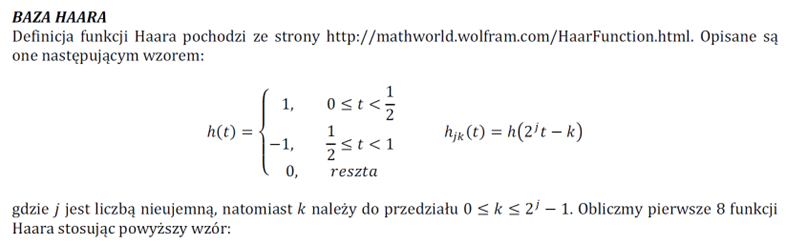

Baza Haara została zaimplementowana jako funkcja Haar_base na końcu dokumentu.

Symulujemy pierwsze osiem szeregów, j = [0,1,2]

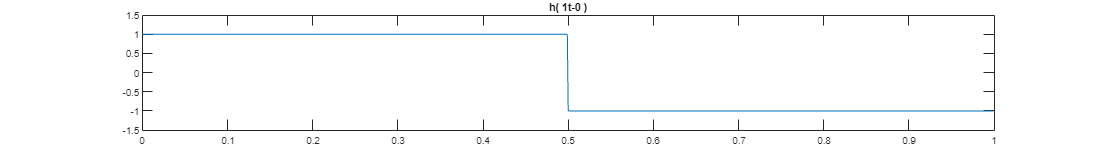

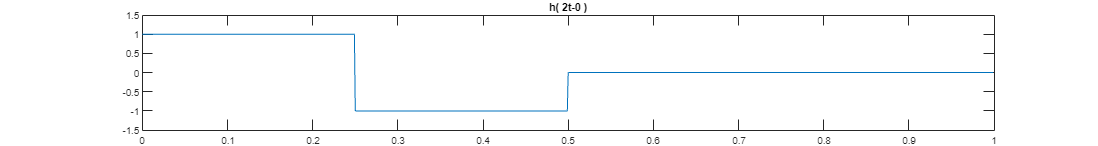

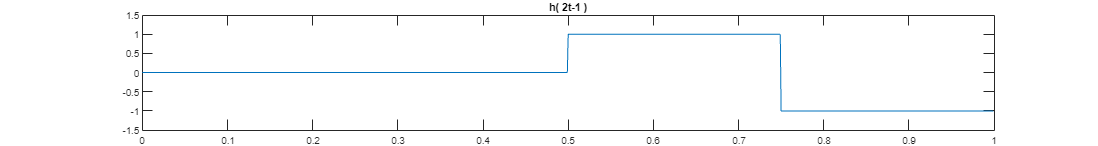

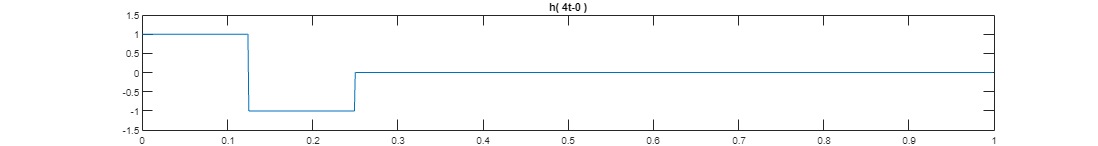

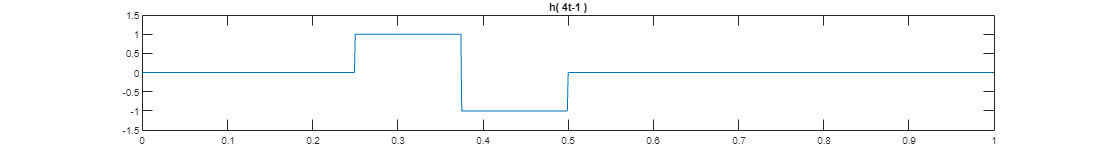

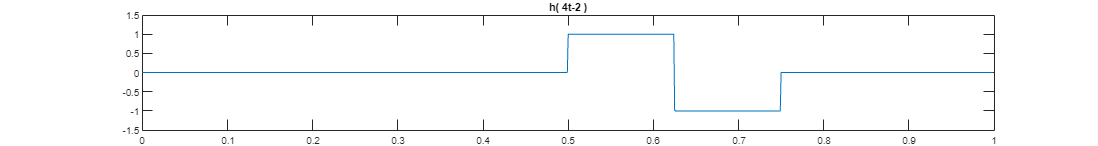

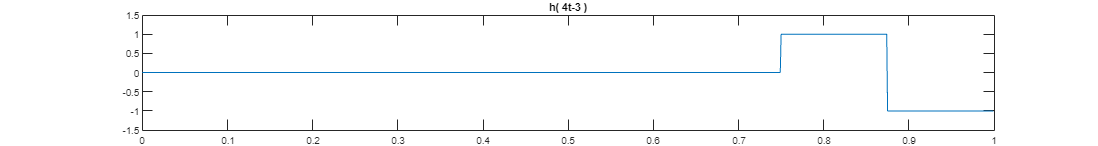

j = [0,1,2];
t = 0:0.001:1-0.001;

for i = 1:length(j)
    for k = 0:(2^j(i))-1;
        h = Haar_base((2^j(i))*t - k);


        fig = figure;
        fig.Position = [0,0,1500,200];
        plot(t, h)
        title(['h( ', int2str(2^j(i)), 't-', num2str(k), ' )'])
        ylim([-1.5, 1.5])
    end
end

## Weryfikacja Twierdzenia Parsevala.

#### Podstawy matematyczne:

**Twierdzenie Parsevala**– tożsamość, która wynika z własności unitarności transformacji Fouriera, co nieformalnie można określić, że suma (lub całka) kwadratu funkcji równa się sumie (lub całce) kwadratu jej transformaty.

Twierdzenie Parsevala w postaci dla Dyskretnej Transformaty Fouriera

#### Symulacja:

Zdefiniujmy sygnał x = [2,5,8,16,65,45]

lewa strona równania "LHS" będzie równa

x = [2,5,8,16,31,45];
LHS = sum(x.^2)

LHS = 3335

następnie wyliczamy prawą stronę równania

X = fft(x);
N = length(X);
RHS = 1/N * sum(abs(X).^2)

RHS = 3335

Lewa i prawa strona są sobie równe. Twierdzenie zostało zweryfikowane pomyślnie.

## Aproksymacja przebiegu trójkątnego i sinusoidalnego szeregiem Walsha (4,16). Błąd średniokwadratowy.

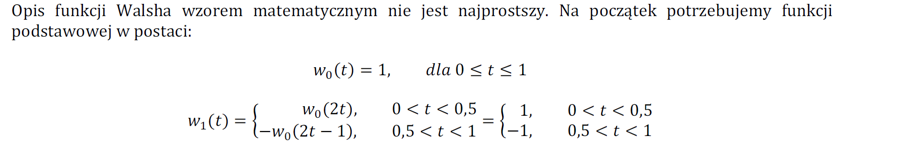

Liczba próbek sygnału musi wynosić N = 2^n

W związku z tym, że baza welsza jest ortonormalna, możemy wykonać odwrotną transformatę bez potrzeby stosowania schematów jak w bazie Haara.

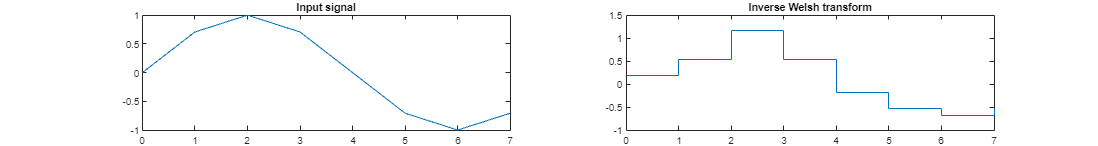

clc; clear all; close all;
N = 8;
n = 0:N-1;



sig = sin(2*pi*n/N);

walsh_base = [1  1  1  1  1  1  1  1; ...
              1  1  1  1 -1 -1 -1 -1; ...
              1  1 -1 -1 -1 -1  1  1; ...
              1  1 -1 -1  1  1 -1 -1; ...
              1 -1 -1  1  1 -1  1  1; ...
              1 -1 -1  1 -1  1 -1 -1; ...
              1 -1  1 -1 -1  1 -1  1; ...
              1 -1  1 -1  1 -1  1 -1];

walsh_transform = (1/N) * sig * walsh_base;

inverse_walsh_transform = walsh_transform * walsh_base;

fig = figure;
fig.Position = [0,0,1500,200];
subplot(1, 2, 1)
plot(n, sig)
title('Input signal')
subplot(1,2,2)
stairs(n, inverse_walsh_transform)
title('Inverse Welsh transform')

Aby transformować sygnał o większej ilości próbek generuję bazę Hadamarda

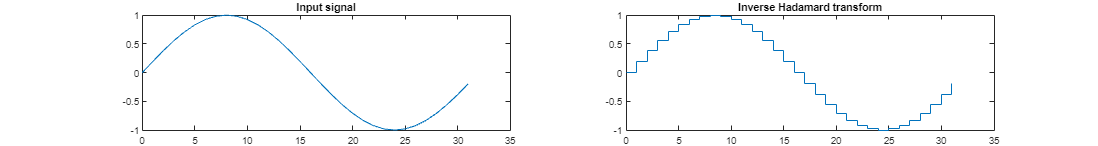

N = 2^5;
n = 0:N-1;

sig = sin(2*pi*n/N);

Hadamard_base = hadamard(N);

hadamard_transform = (1/N) * sig * Hadamard_base;

inverse_hadamard_transform = hadamard_transform * Hadamard_base;


fig = figure;
fig.Position = [0,0,1500,200];
subplot(1, 2, 1)
plot(n, sig)
title('Input signal')
subplot(1,2,2)
stairs(n, inverse_hadamard_transform)
title('Inverse Hadamard transform')

function X = Dot_product(x, y)
    X = 0;
    for i = 1:length(y)
        X = X + x(i) * y(i);
    end
end

function x_length = Vector_length(x)
    x_length = 0;
    for i = 1:length(x)
        x_length = x_length + x(i)^2;
    end
    x_length = sqrt(x_length);
end

function V_norm = Vector_normalise(x)
    x_length = Vector_length(x);
    for i = 1:length(x)
        x(i) = x(i)/(x_length);
    end
    V_norm = x;
end

function H = Haar_base(t)
    H = zeros(1, length(t));
    for i = 1:length(t)
        if (t(i) >= 0) && (t(i) < 1/2)
            H(i) = 1;
        elseif (t(i) >= 1/2) && (t(i) < 1)
            H(i) = -1;
        else
            H(i) = 0;
        end
    end
end